# AOI_Lab : BardcodeRead

#### Fred liu 2023.07.12

使用readBarcode的指令可以辨識一維與二維的條碼

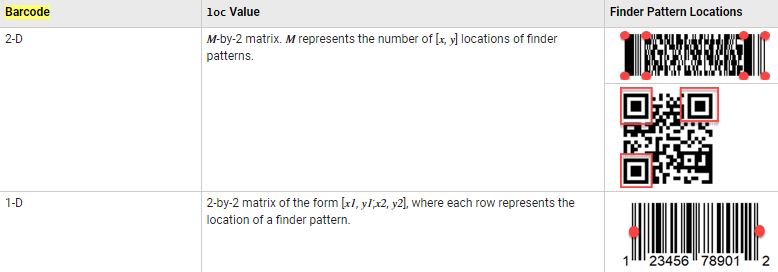

I = imread("code03.jpg");
[msg, ~, loc] = readBarcode(I);

% Annotate the image with the decoded message.
xyText =  loc(1,:);
Imsg = insertText(I, xyText, msg, "BoxOpacity", 1, "FontSize", 25);
disp(msg)

https://medium.com/@FredLiu_


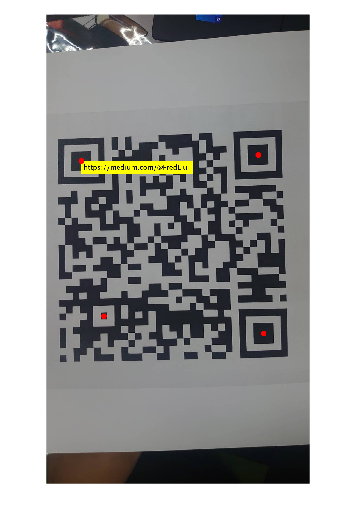

% Insert filled circles at the finder pattern locations.
Imsg = insertShape(Imsg, "FilledCircle", [loc, ...
    repmat(10, length(loc), 1)], "Color", "red", "Opacity", 1);

% Display image.
imshow(Imsg)

`format`** — Barcode format**

`'all'` — Use this option to specify all valid barcode formats. If you do not specify a format, the function uses this option.

`'1D'` — Use this option to specify all valid 1-D barcode formats.

`'2D'` — Use this option to specify all valid 2-D barcode formats

1-D Formats

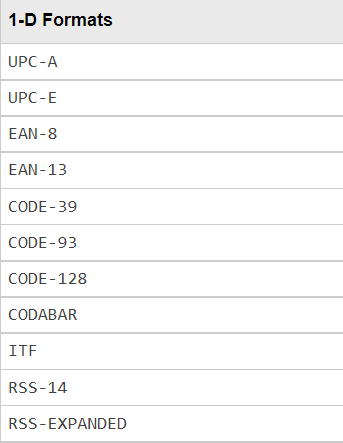

2-D Formats